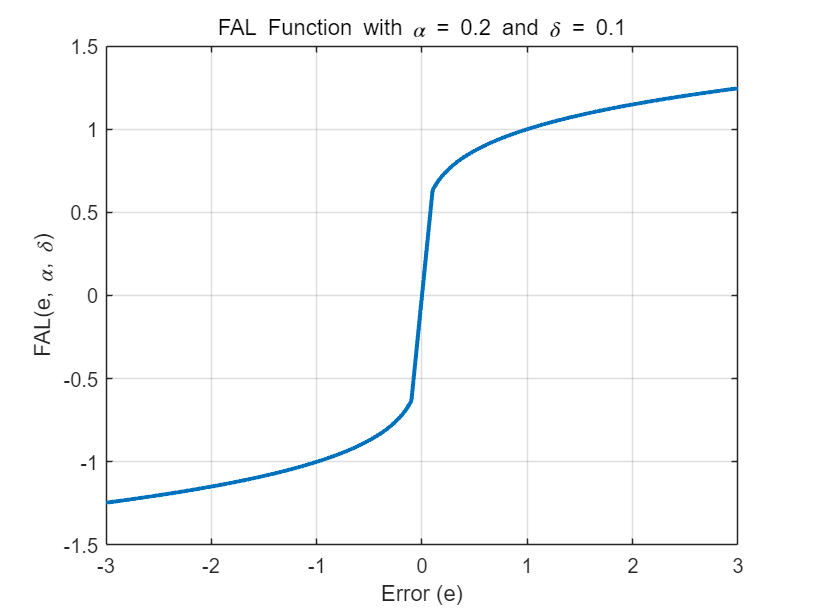

% Parameters
alpha = 0.2; % Nonlinear term exponent
delta = 0.1; % Small positive number

% Define the FAL function
fal = @(e, alpha, delta) (abs(e).^alpha .* sign(e)) .* (abs(e) >= delta) + (e ./ delta^(1 - alpha)) .* (abs(e) < delta);

% Generate a range of error values
e = linspace(-3, 3, 1000);

% Compute the FAL function values
fal_values = fal(e, alpha, delta);

% Plot the FAL function
figure;
plot(e, fal_values, 'LineWidth', 2);
xlabel('Error (e)');
ylabel('FAL(e, \alpha, \delta)');
title(['FAL Function with \alpha = ', num2str(alpha), ' and \delta = ', num2str(delta)]);
grid on;